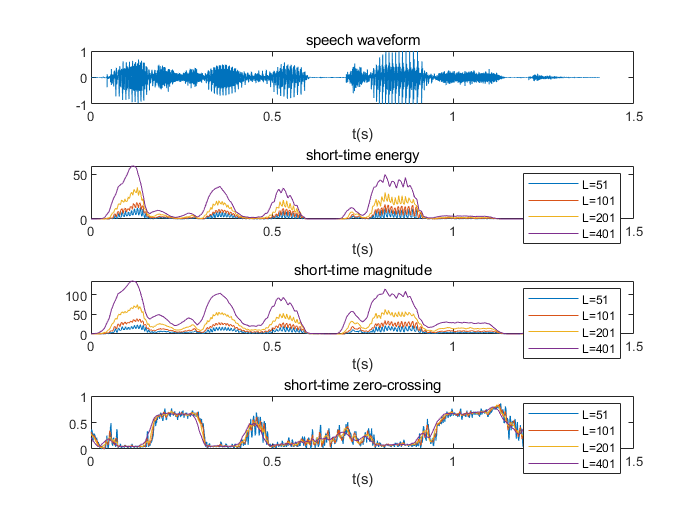

[s,fs]=audioread('test_16k.wav');
N=length(s);
L1=51;
L2=101;
L3=201;
L4=401;
R1=round((L1-1)/4);
R2=round((L2-1)/4);
R3=round((L3-1)/4);
R4=round((L4-1)/4);
rectabgular1=rectwin(L1);
rectabgular2=rectwin(L2);
rectabgular3=rectwin(L3);
rectabgular4=rectwin(L4);
ham1=hamming(L1);
ham2=hamming(L2);
ham3=hamming(L3);
ham4=hamming(L4);

[E1,M1,Z1]=EMZ(s,L1,R1,rectabgular1);
[E2,M2,Z2]=EMZ(s,L2,R2,rectabgular2);
[E3,M3,Z3]=EMZ(s,L3,R3,rectabgular3);
[E4,M4,Z4]=EMZ(s,L4,R4,rectabgular4);
[E5,M5,Z5]=EMZ(s,L1,R1,ham1);
[E6,M6,Z6]=EMZ(s,L2,R2,ham2);
[E7,M7,Z7]=EMZ(s,L3,R3,ham3);
[E8,M8,Z8]=EMZ(s,L4,R4,ham4);
figure
subplot(4,1,1);
plot(0:1/fs:(N-1)/fs,s);
title('speech waveform');
xlabel('t(s)');

subplot(4,1,2);
plot(0:1/(fs/R1):(floor(N/R1)-1)/(fs/R1),E1);
hold on
plot(0:1/(fs/R2):(floor(N/R2)-1)/(fs/R2),E2);
hold on
plot(0:1/(fs/R3):(floor(N/R3)-1)/(fs/R3),E3);
hold on
plot(0:1/(fs/R4):(floor(N/R4)-1)/(fs/R4),E4);
legend('L=51','L=101','L=201','L=401');
title('short-time energy');
xlabel('t(s)');

subplot(4,1,3);
plot(0:1/(fs/R1):(floor(N/R1)-1)/(fs/R1),M1);
hold on
plot(0:1/(fs/R2):(floor(N/R2)-1)/(fs/R2),M2);
hold on
plot(0:1/(fs/R3):(floor(N/R3)-1)/(fs/R3),M3);
hold on
plot(0:1/(fs/R4):(floor(N/R4)-1)/(fs/R4),M4);
legend('L=51','L=101','L=201','L=401');
title('short-time magnitude');
xlabel('t(s)');

subplot(4,1,4);
plot(0:1/(fs/R1):(floor(N/R1)-1)/(fs/R1),Z1);
hold on
plot(0:1/(fs/R2):(floor(N/R2)-1)/(fs/R2),Z2);
hold on
plot(0:1/(fs/R3):(floor(N/R3)-1)/(fs/R3),Z3);
hold on
plot(0:1/(fs/R4):(floor(N/R4)-1)/(fs/R4),Z4);
legend('L=51','L=101','L=201','L=401');
title('short-time zero-crossing');
xlabel('t(s)');

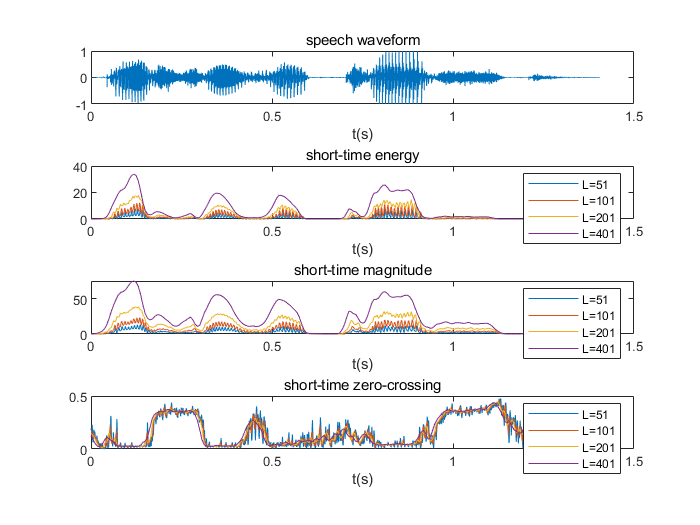


figure
subplot(4,1,1);
plot(0:1/fs:(N-1)/fs,s);
title('speech waveform');
xlabel('t(s)');

subplot(4,1,2);
plot(0:1/(fs/R1):(floor(N/R1)-1)/(fs/R1),E5);
hold on
plot(0:1/(fs/R2):(floor(N/R2)-1)/(fs/R2),E6);
hold on
plot(0:1/(fs/R3):(floor(N/R3)-1)/(fs/R3),E7);
hold on
plot(0:1/(fs/R4):(floor(N/R4)-1)/(fs/R4),E8);
legend('L=51','L=101','L=201','L=401');
title('short-time energy');
xlabel('t(s)');

subplot(4,1,3);
plot(0:1/(fs/R1):(floor(N/R1)-1)/(fs/R1),M5);
hold on
plot(0:1/(fs/R2):(floor(N/R2)-1)/(fs/R2),M6);
hold on
plot(0:1/(fs/R3):(floor(N/R3)-1)/(fs/R3),M7);
hold on
plot(0:1/(fs/R4):(floor(N/R4)-1)/(fs/R4),M8);
legend('L=51','L=101','L=201','L=401');
title('short-time magnitude');
xlabel('t(s)');

subplot(4,1,4);
plot(0:1/(fs/R1):(floor(N/R1)-1)/(fs/R1),Z5);
hold on
plot(0:1/(fs/R2):(floor(N/R2)-1)/(fs/R2),Z6);
hold on
plot(0:1/(fs/R3):(floor(N/R3)-1)/(fs/R3),Z7);
hold on
plot(0:1/(fs/R4):(floor(N/R4)-1)/(fs/R4),Z8);
legend('L=51','L=101','L=201','L=401');
title('short-time zero-crossing');
xlabel('t(s)');